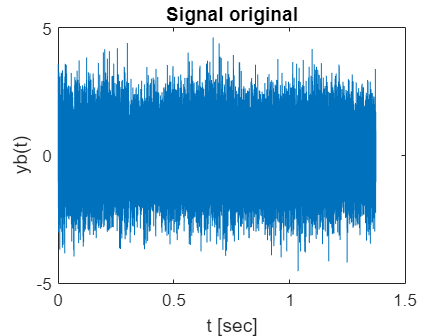

clear all;
close all;

% Clavier téléphone

% chargement des données: le signal s'appelle 'yb'
load('seqclavier.mat');
Fe=32768;

% tracé
N=length(yb);
k=0:N-1;
t=k/Fe;
figure(1);
plot(t, yb);
xlabel('t [sec]'); ylabel('yb(t)');
title('Signal original');

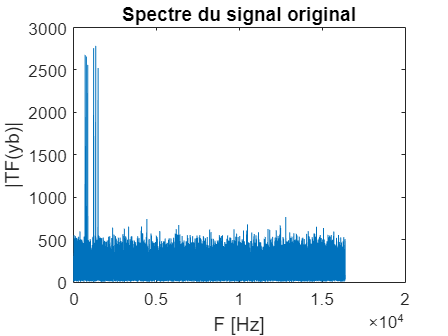


% spectre
nfft=2^nextpow2(4*N);
Yb=abs(fft(yb, nfft)); 
Yb=Yb(1:nfft/2);
F=[0:nfft/2-1]/nfft*Fe;
figure(2); plot(F, Yb);
xlabel('F [Hz]'); ylabel('|TF(yb)|'); title('Spectre du signal original');

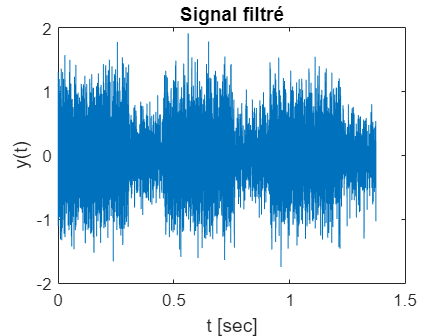


% filtrage
Fc=1600;
[B, A]=butter(4, 2*Fc/Fe);
y = filtfilt(B, A, yb);
figure(3); plot(t, y); xlabel('t [sec]'); ylabel('y(t)'); title('Signal filtré');

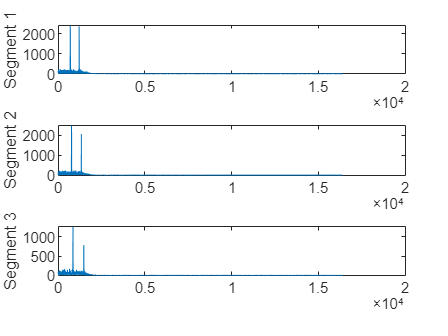


% segmentation
y1 = y(1:10000); Y1=abs(fft(y1, nfft)); Y1=Y1(1:nfft/2);
y2 = y(15001:25000); Y2=abs(fft(y2, nfft)); Y2=Y2(1:nfft/2);
y3 = y(30001:35000); Y3=abs(fft(y3, nfft)); Y3=Y3(1:nfft/2);

figure;
subplot(3,1,1); plot(F, Y1); ylabel('Segment 1');
subplot(3,1,2); plot(F, Y2); ylabel('Segment 2');
subplot(3,1,3); plot(F, Y3); ylabel('Segment 3');


% touches 1-5-9

